## Simple Simulation

t = 0:0.01:5;
% u = [cos(t)' 5000*ones(size(t))'];
u = [deg2rad(10)*ones(size(t))' 1000*ones(size(t))'];
z0 = zeros(6,1);
z0(2) = 8.9;
[Y, T] = forwardIntegrateControlInput(u, z0);
figure;


### States

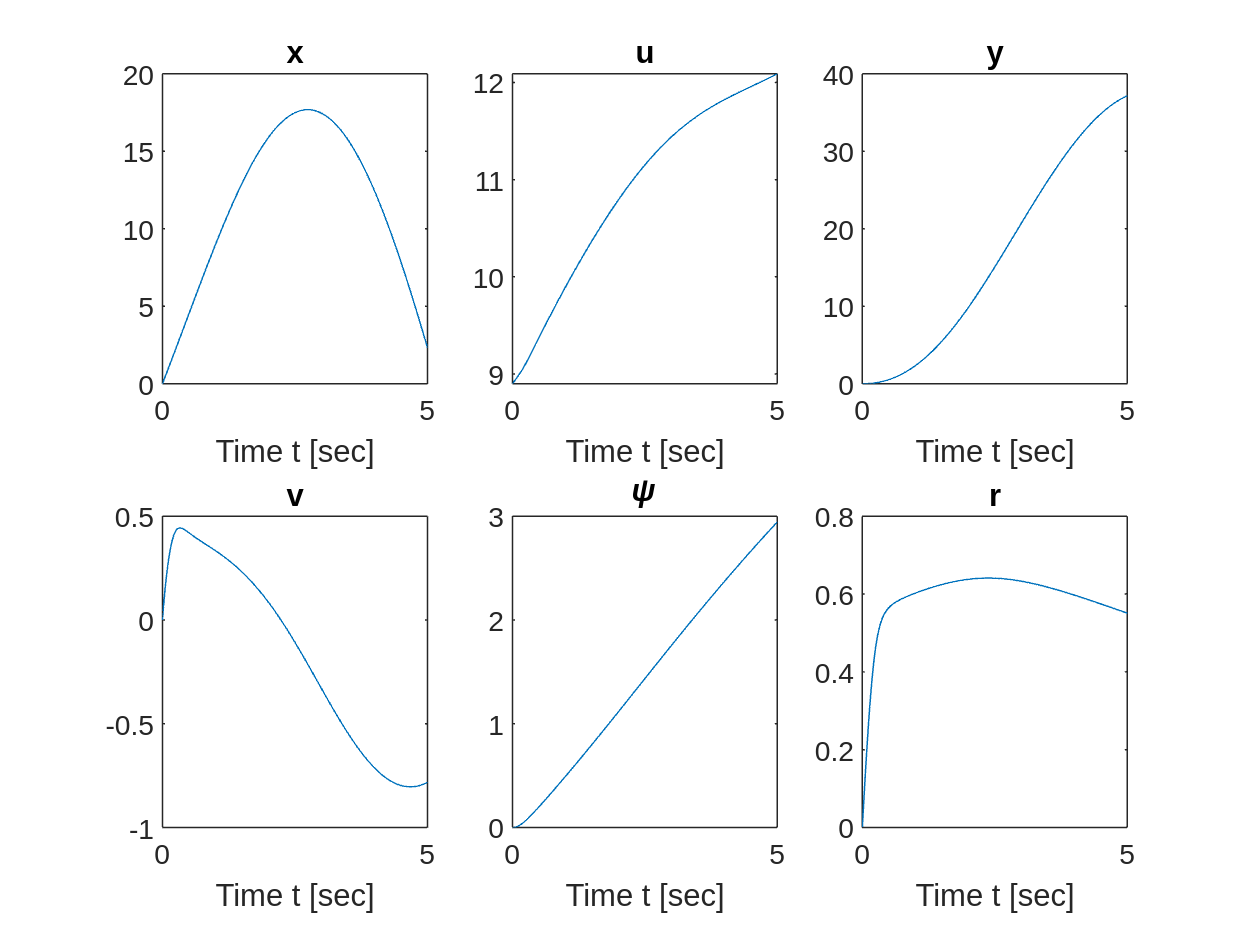

titles = ["x"; "u"; "y"; "v"; "\psi"; "r"];
for i = 1:6
    subplot(2,3,i)
    plot(T,Y(:,i))
    title(titles(i))
    xlabel('Time t [sec]')
end

### Trajectory

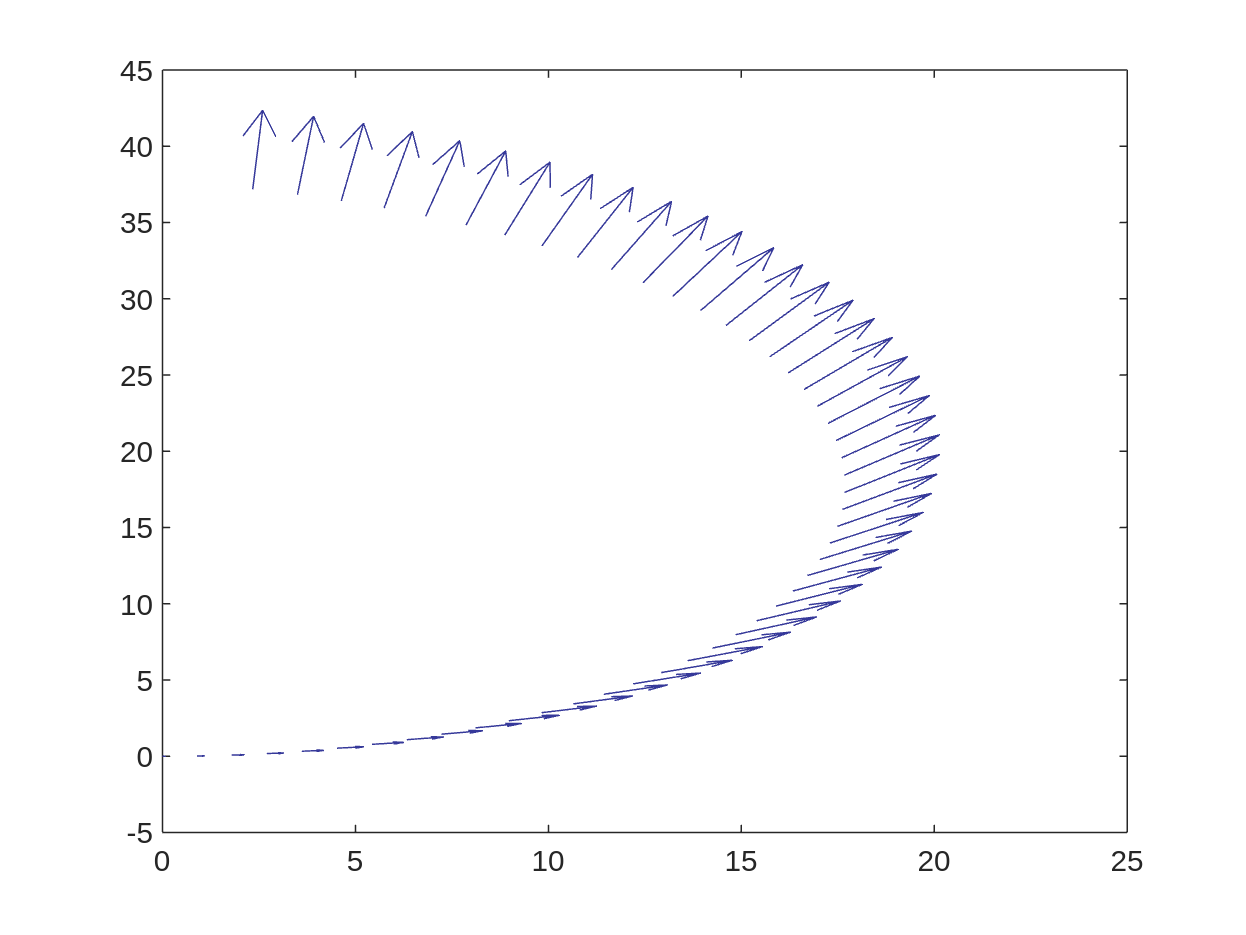

x = Y(:,1); u = Y(:,2); y = Y(:,3); v = Y(:,4); psi = Y(:,5); r = Y(:,6);
figure;
quiver(x(1:10:end,1), y(1:10:end,1), x(1:10:end,1) + 0.5*cos(psi(1:10:end,1)), y(1:10:end,1) + 0.5*sin(psi(1:10:end,1)), 'Color', '#36399a')

## Simple Controller

Given waypoint travel in x first then y

setpoint = [180 65 pi/4]';
tspan = t;
u = braindeadController(setpoint,tspan )

Dot indexing is not supported for variables of this type.

Error in braindeadController (line 4)
    pos_diff = track.cline - [X(1); X(3)];